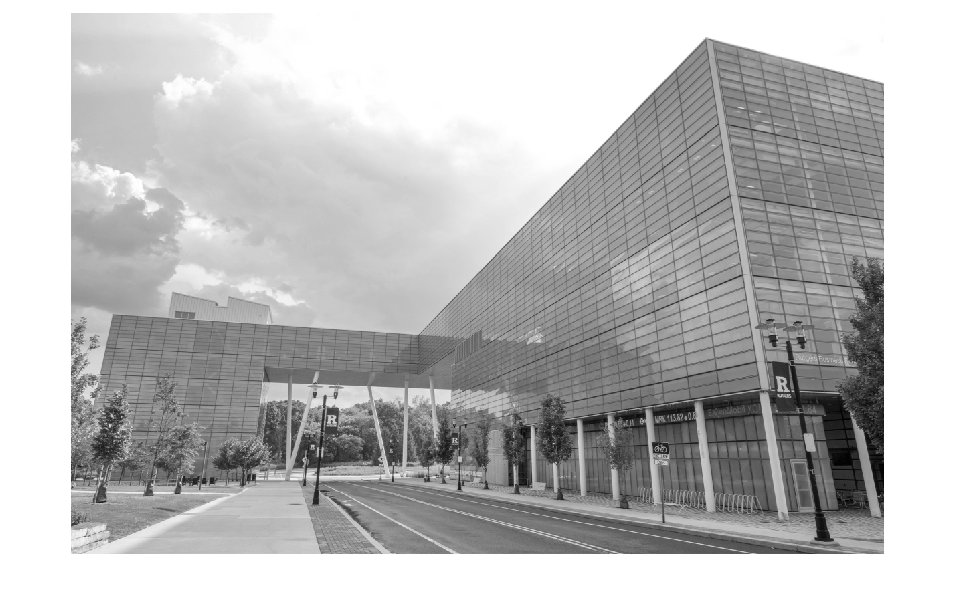

clear; close all; clc;

%% --- Load and prepare image ---
X_color = imread('Livingston.png');
if ndims(X_color) == 3
    X_gray = rgb2gray(X_color);
else
    X_gray = X_color;
end
X = double(X_gray);
figure(); imshow(X, []);

[r, c] = size(X);
fprintf('Original image size: %d x %d\n', r, c);

Original image size: 810 x 1215


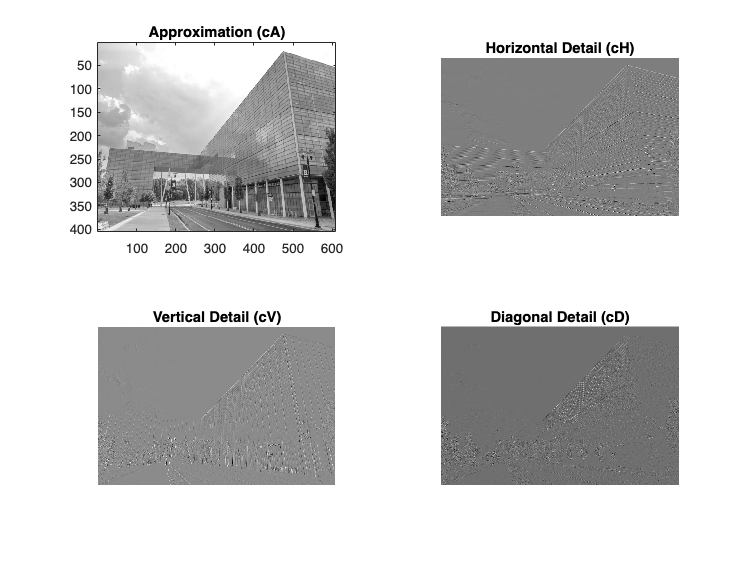




%% --- Perform 2D DWT (Haar wavelet) ---
[LoD, HiD] = wfilters('haar', 'd');
[cA, cH, cV, cD] = dwt2(X, LoD, HiD, 'mode', 'symh');

figure('Name','DWT Coefficients');
tiledlayout(2,2);
nexttile; imagesc(cA); colormap gray; title('Approximation (cA)');
nexttile; imshow(cH,[]); title('Horizontal Detail (cH)');
nexttile; imshow(cV,[]); title('Vertical Detail (cV)');
nexttile; imshow(cD,[]); title('Diagonal Detail (cD)');




%% --- Compare filter energies ---
E_low = sum(LoD.^2);
E_high = sum(HiD.^2);
fprintf('Energy of lowpass filter: %.4f\n', E_low);

Energy of lowpass filter: 1.0000


fprintf('Energy of highpass filter: %.4f\n', E_high);

Energy of highpass filter: 1.0000





%% --- Reconstruct image from DWT ---
A0 = idwt2(cA, cH, cV, cD, 'haar', 'mode', 'symh');


% Check size correction
A0 = A0(1:r, 1:c); % ensure same dimensions


% Compute difference and errors
diff_img = X - A0;
total_sq_error = sum(diff_img(:).^2) / numel(X);
max_abs_diff = max(abs(diff_img(:)));

fprintf('Total squared error per pixel: %.6f\n', total_sq_error);

Total squared error per pixel: 0.000000


fprintf('Max absolute difference: %.4f\n', max_abs_diff);

Max absolute difference: 0.0000



% Find largest absolute difference pixel
[maxVal, maxIdx] = max(abs(diff_img(:)));
[rowMax, colMax] = ind2sub(size(diff_img), maxIdx);
fprintf('Max difference at (row=%d, col=%d), value=%.2f\n', rowMax, colMax, diff_img(rowMax, colMax));

Max difference at (row=99, col=1194), value=-0.00


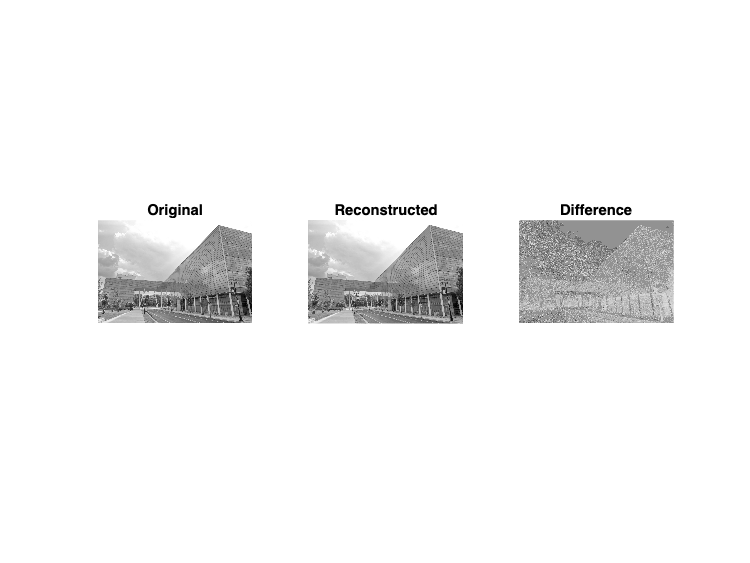


figure('Name','Reconstruction Comparison');
subplot(1,3,1); imshow(X,[]); title('Original');
subplot(1,3,2); imshow(A0,[]); title('Reconstructed');
subplot(1,3,3); imshow(diff_img,[]); title('Difference');

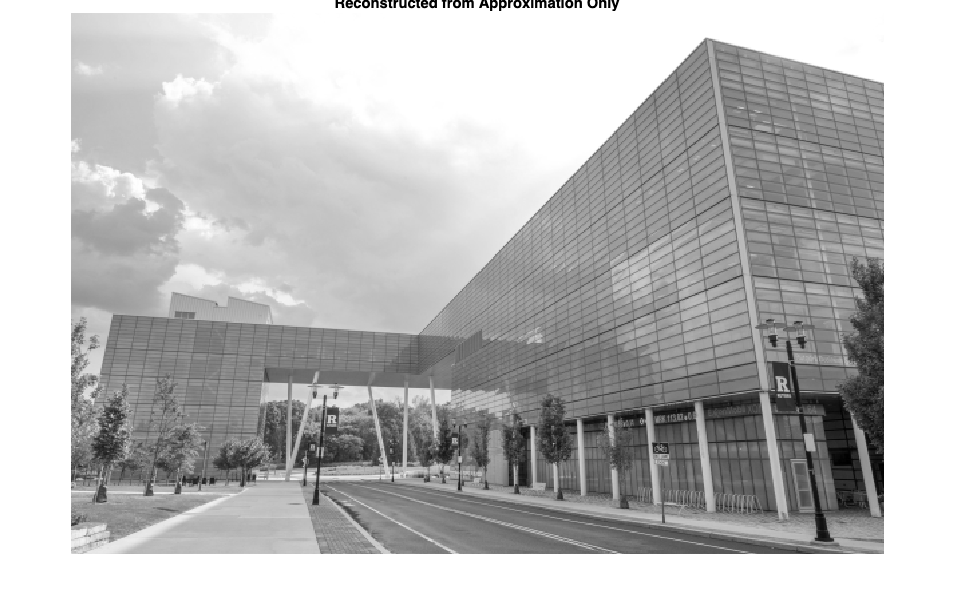


figure(); imshow(diff_img); colormap gray;

%% --- Crude compression using approximation only ---
cH_zero = zeros(size(cH));
cV_zero = zeros(size(cV));
cD_zero = zeros(size(cD));

A_lowdetail = idwt2(cA, cH_zero, cV_zero, cD_zero, 'haar', 'mode', 'symh');
A_lowdetail = A_lowdetail(1:r,1:c);

figure('Name','Low Detail Reconstruction');
imshow(A_lowdetail,[]); colormap gray;
title('Reconstructed from Approximation Only');



% Compute compression ratio
num_original = numel(X);
num_dwt = numel(cA) + numel(cH) + numel(cV) + numel(cD);
compression_ratio = num_original / numel(cA);
fprintf('Compression ratio (approximation only): %.2f:1\n', compression_ratio);

Compression ratio (approximation only): 4.00:1



% Difference between low detail and original
diff_low = X - A_lowdetail;
sq_error_low = sum(diff_low(:).^2) / numel(X);
max_abs_low = max(abs(diff_low(:)));
fprintf('Low-detail squared error per pixel: %.6f\n', sq_error_low);

Low-detail squared error per pixel: 68.012464


fprintf('Low-detail max absolute diff: %.4f\n', max_abs_low);

Low-detail max absolute diff: 89.0000


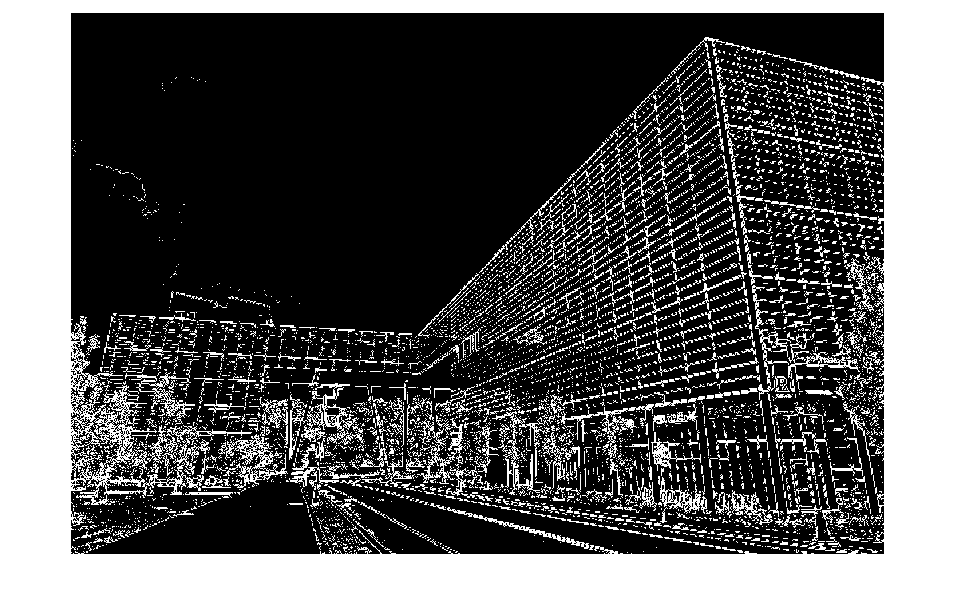


% Thresholded difference visualization
tau = 10;
diff_thresh = abs(diff_low) > tau;
figure('Name','Thresholded Difference');
imshow(diff_thresh,[]);

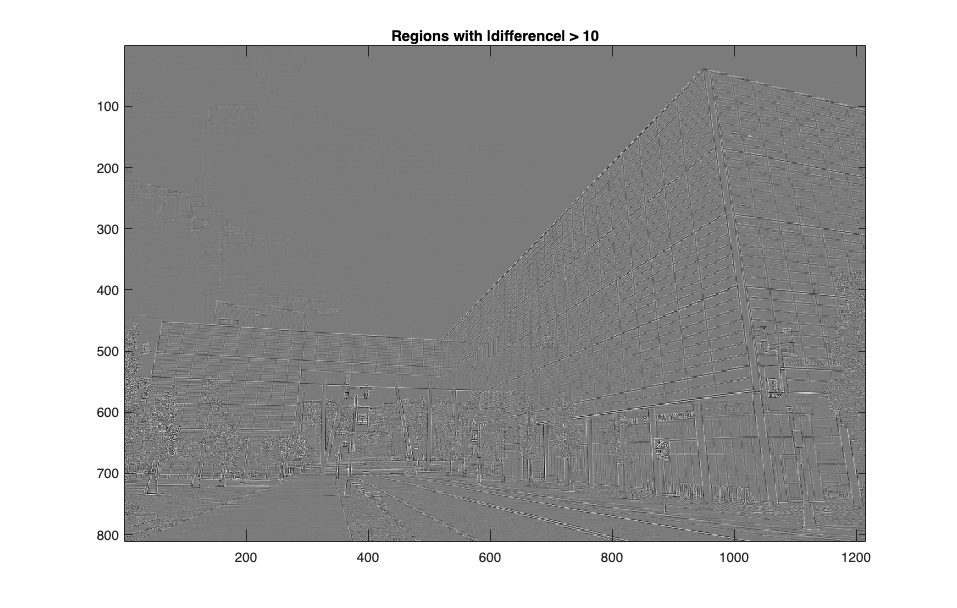

imagesc(diff_low);
colormap gray;
title(['Regions with |difference| > ', num2str(tau)]);